real = csvread('exit_tratada.csv', 1);
real_data = struct( ...
    'Setpoint', real(50:3854, 3) - 25.95, ...
    'Control_Signal', real(50:3854, 2), ...
    'Controlled_Variable', real(50:3854, 1) - 25.95, ...
    'Mode', real(50:3854, 4) ...
);

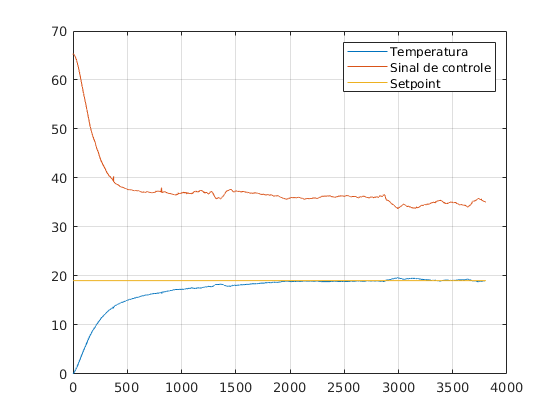

plot(real_data.Controlled_Variable)
hold on
plot(real_data.Control_Signal),
plot(real_data.Setpoint)
legend('Temperatura', 'Sinal de controle', 'Setpoint')
hold off
grid on

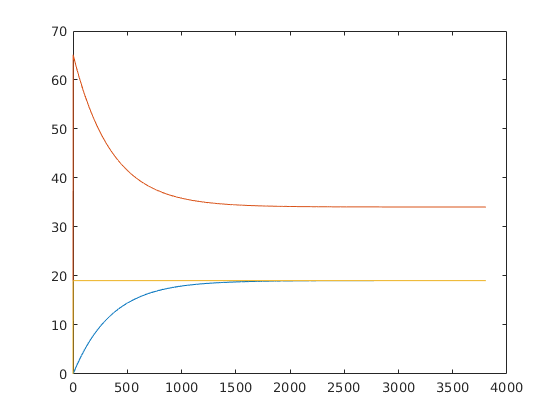


plot(simulated.Controlled_Variable.Time, simulated.Controlled_Variable.Data)
hold on
plot(simulated.Controlled_Variable.Time, simulated.Control_Signal.Data),
plot(simulated.Controlled_Variable.Time, simulated.Setpoint.Data)
hold off

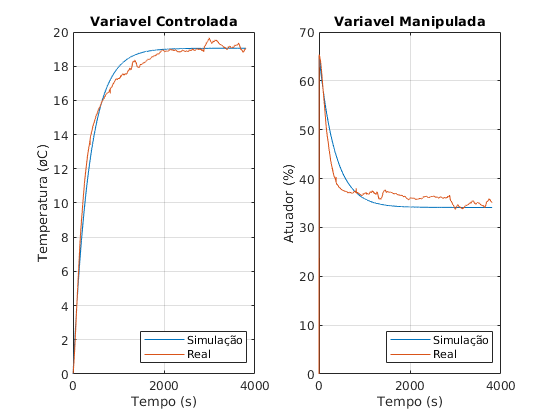

fig = gcf;
fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 6 3];

subplot(1, 2, 1)
plot(simulated.Controlled_Variable.Time, simulated.Controlled_Variable.Data)
hold on
plot(real_data.Controlled_Variable)
hold off

grid on
title('Variavel Controlada')
xlabel('Tempo (s)')
ylabel('Temperatura (øC)')
legend('Simulação', 'Real', 'Location','southeast')

subplot(1, 2, 2)
plot(simulated.Controlled_Variable.Time, simulated.Control_Signal.Data)
hold on
plot(real_data.Control_Signal)
hold off

grid on
title('Variavel Manipulada')
xlabel('Tempo (s)')
ylabel('Atuador (%)')
legend('Simulação', 'Real', 'Location', 'southeast')

fprintf('%s: %f' ,'Erro do sinal de controle', ...
    mean((simulated.Control_Signal.Data - real_data.Control_Signal) .^ 2))

Erro do sinal de controle: 5.009000

fprintf('%s: %f' ,'Erro da variavel controlada', ...
    mean((simulated.Controlled_Variable.Data - real_data.Controlled_Variable) .^ 2))

Erro da variavel controlada: 0.262235